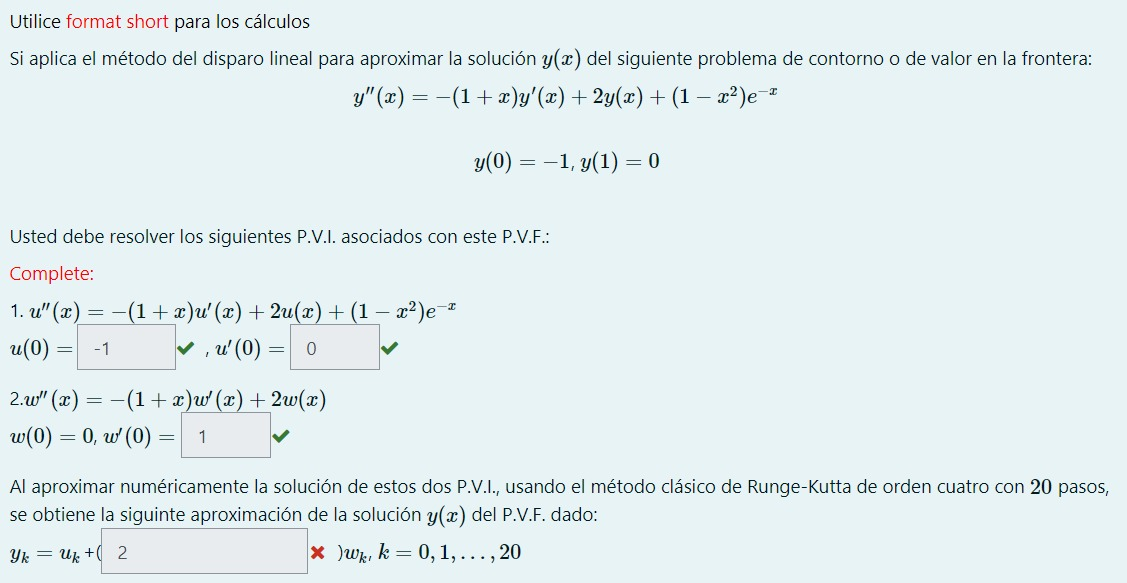

a = 0; b = 1; M = 20;
F1 = @(t,U) [U(2), -(1+t).*U(2)+2.*U(1)+(1-t.^2).*exp(-t)]

F1 = function_handle with value:
    @(t,U)[U(2),-(1+t).*U(2)+2.*U(1)+(1-t.^2).*exp(-t)]


F2 = @(t,U) [U(2), -(1+t).*U(2)+2.*U(1)];
Za1 = [-1 0]; Za2 = [0 1];
[T1, Z1] = rks4 (F1, a, b, Za1, M);
[T1' Z1]

ans =          0   -1.0000         0
    0.0500   -1.0013   -0.0500
    0.1000   -1.0050   -0.1001
    0.1500   -1.0113   -0.1504
    0.2000   -1.0201   -0.2010
    0.2500   -1.0314   -0.2517
    0.3000   -1.0452   -0.3028
    0.3500   -1.0616   -0.3540
    0.4000   -1.0806   -0.4055
    0.4500   -1.1022   -0.4570


[T2, Z2] = rks4 (F2, a, b, Za2, M);
[T2' Z2]

ans =          0         0    1.0000
    0.0500    0.0488    0.9525
    0.1000    0.0953    0.9097
    0.1500    0.1398    0.8714
    0.2000    0.1825    0.8373
    0.2500    0.2236    0.8073
    0.3000    0.2633    0.7811
    0.3500    0.3018    0.7584
    0.4000    0.3392    0.7390
    0.4500    0.3758    0.7227


coef = (0-(-1.5091))/(0.7546)

coef = 1.9999

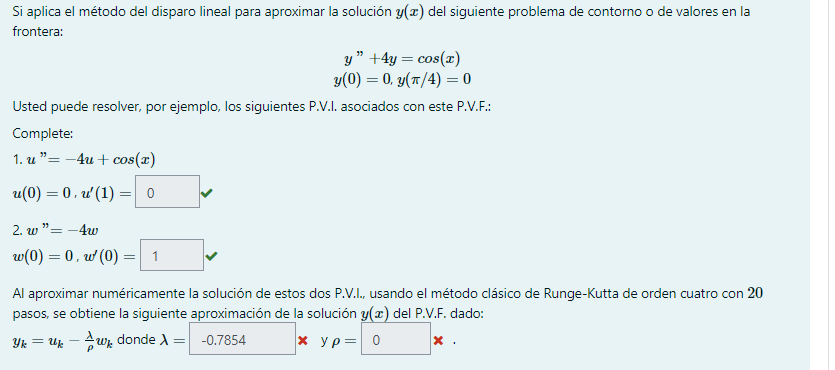

F1 = @(t,U) [U(2), -4.*U(1)+cos(t)];
F2 = @(t,U) [U(2), -4.*U(1)];
a = 0; b = pi/4; M = 20;
Za1 = [0 0]; Za2 = [0 1];
[T1,Z1] = rks4(F1,a,b,Za1,M);
[T1' Z1]

ans =          0         0         0
    0.0393    0.0008    0.0392
    0.0785    0.0031    0.0781
    0.1178    0.0069    0.1165
    0.1571    0.0122    0.1539
    0.1963    0.0190    0.1901
    0.2356    0.0271    0.2248
    0.2749    0.0366    0.2579
    0.3142    0.0473    0.2889
    0.3534    0.0593    0.3176


[T2,Z2] = rks4(F2,a,b,Za2,M);
[T2' Z2]

ans =          0         0    1.0000
    0.0393    0.0392    0.9969
    0.0785    0.0782    0.9877
    0.1178    0.1167    0.9724
    0.1571    0.1545    0.9511
    0.1963    0.1913    0.9239
    0.2356    0.2270    0.8910
    0.2749    0.2612    0.8526
    0.3142    0.2939    0.8090
    0.3534    0.3247    0.7604


syms t y
f = 2*t*(y^2);
a = 0; b = 1; h = 0.2; M = (b-a)/h; n = 2; ya = 1;
T=taylorN(f,n,a,b,ya,M)

T =          0    1.0000
    0.2000    1.0400
    0.4000    1.1770
    0.6000    1.4958
    0.8000    2.3150
    1.0000    5.5149


2*0.8*(2.3150^2)

ans = 8.5748